konstanten

clear;
audioFilename = 'vergleichsaudio.mp3';
w0 = 1;
 
M=256;
nDFT=512;
 
winShift = M/4;       % Verschiebung des Analysefensters 

initialisierung

[y,fs] = audioread(audioFilename);
y=mean(y,2);                %Mittelwert der beiden Spuren in der Audio-Datei
 
%sound(y,fs);
 
N = length(y);              %Anzahl der Abtastpunkte
dt=1/fs;                    %Abtastintervall in der Zeitdomäne
 
 
t = (0:dt:N*dt -dt);        %Abtastzeitpunkte im Zeitraum
 
 
df=fs/nDFT;                 %Abtastintervall im Freqeunzraum
sampleIndex = 0:nDFT/2-1;
f= sampleIndex * df;        % Abtastzeitpunkte im Freqeunzraum
 
 
Dt= winShift * dt *1000     %Zeitauflösung Spektrogramm

Dt = 1.3333


disp(['Zeitauflösung des Spektrogramm ', num2str(Dt), ' ms']);

Zeitauflösung des Spektrogramm 1.3333 ms




Df= fs/nDFT                 %Frequenzauflösung

Df = 93.7500


disp(['Freqeunzauflösung des Spektrogramm ', num2str(Df), ' Hz']);

Freqeunzauflösung des Spektrogramm 93.75 Hz


plotten des oszillogramms

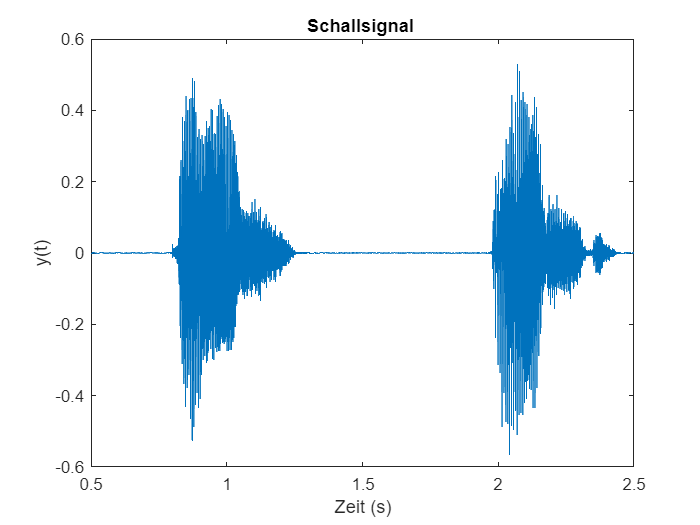

plot(t,y,'LineWidth',0.1);
xlabel('Zeit (s)')
ylabel('y(t)')
title ('Schallsignal ')
xlim([0.5 2.5]);

berechnen spektrogramm

w= w0*hamming(M,'periodic');

n=1;                                        %Counter n für Zeitfenster
 
for tnum = 1:winShift:(N-M)                 %Iteratives Berechnen der SFT
 
  yHam = y(tnum:tnum+M-1).*w(1:M);
  [pHam] = fPowerSpectrum('vergleichsaudio.mp3',yHam,nDFT);
  L=length(pHam);
  P(1:L,n) = pHam(1:L);                     % Merkmalsvektoren in SpektroMatrix speichern  
  tp(n)=tnum*dt;
  n=n+1;
 
end

Arrays have incompatible sizes for this operation.

Error in fPowerSpectrum (line 32)
Y(abs(Y) < tol) = 0;

Related documentation

speichern spektrogramm als objekt

save('spektrogram/spektrogram.mat','P');

plotten spektrogramm

figure(10)
surf(tp(2:end),f,P(:,2:end),'edgecolor','none'); axis tight;view(0,90);
%colormap(gray);
colormap(jet);
colorbar;
set(gca,'clim',[-90 -10]);      %clim is the limits of the axis colours
xlabel('Zeit (s)');
ylabel('Frequenz (Hz)')
xlim([0.7 2.5]);
ylim([50 4000]);
zlim([-90, -10]);